# Plot PPG signal and absorption coefficient  

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter6/PlotPPG'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Ploting AC and DC component of the PPG signal

clear_all_but('SAVE_FLAG')
load('plethy1.mat')
fs=39;
t=1/fs:1/fs:length(b1)/fs;
f1=figure

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


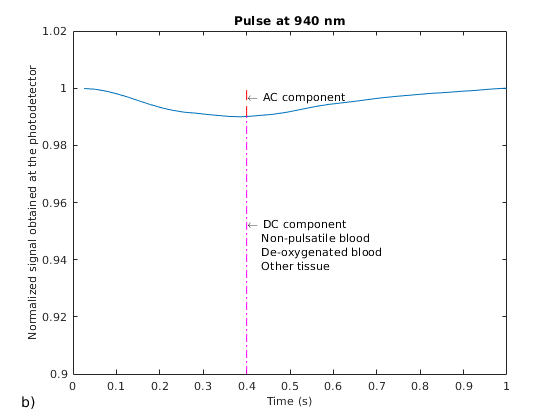


plot(t,(100-b1)/100)
ylabel('Normalized signal obtained at the photodetector', 'FontSize', 10)
xlabel('Time (s)', 'FontSize', 10)
ylim([0.9,1.02])
a3=line([0.4 0.4],[0.9 0.9902],'Color','magenta','LineStyle','-.');
a2=line([0.4 0.4],[0.9902 1],'Color','red','LineStyle','--');
%text(0.4,0.945,'\leftarrow DC component')
text(0.4,0.945,{'\leftarrow DC component', '    Non-pulsatile blood', '    De-oxygenated blood', '    Other tissue'})
text(0.4,0.997,'\leftarrow AC component')
title("Pulse at 940 nm")
%saveas(f1, 'Fig6.1b.jpg')
annonation_save('b)',"Fig6.1b.jpg", SAVE_FLAG);

## Ploting the absorption coefficient vs. wavelelngth

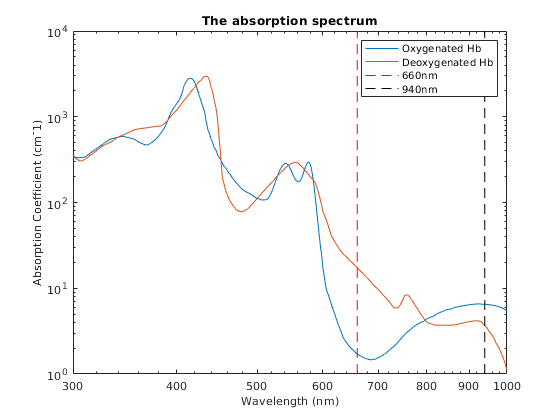

%Ploting mua
load('spectralLIB.mat')
f2=figure;
ylimreg=ylim;
wav=300:1000;
a1=loglog(wav,muaoxy); M1="Oxygenated Hb";
hold on,
a2=loglog(wav,muadeoxy); M2="Deoxygenated Hb";

a3=line([660 660],ylim,'Color','red','LineStyle','--'); M3="660nm";
a4=line([940 940],ylim,'Color','black','LineStyle','--'); M4="940nm";
legend([a1,a2,a3,a4], [M1, M2,M3,M4]);
xlabel('Wavelength (nm)', 'FontSize', 10)
ylabel('Absorption Coefficient (cm^-1)', 'FontSize', 10)
title('The absorption spectrum')
%saveas(f2, 'Fig6.4.jpg')
annonation_save('',"Fig6.4.jpg", SAVE_FLAG);

## PPG pulse and the spectrum

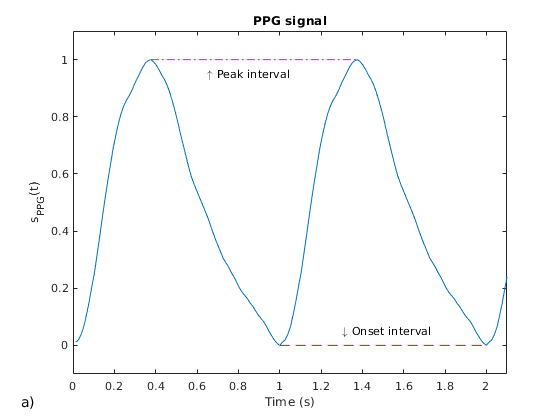


% Generate Data
clear_all_but('SAVE_FLAG')
load('plethy.mat');
a1=rescale1([a;a;a;a;a;a;a;a;a;a]);
fs=77;
T=1/fs;
t=T:T:length(a1)*T;
f3=figure;
plot(t,a1)
title('PPG signal')
xlabel('Time (s)')
ylabel('s_{PPG}(t)')
xlim([0 2.1])
ylim([-0.1 1.1])
a3=line([0.3766 1.3766],[1 1],'Color','magenta','LineStyle','-.');
a2=line([1 2],[0 0],'Color','red','LineStyle','--');
%text(0.4,0.945,'\leftarrow DC component')
text(0.65,0.95,{'\uparrow Peak interval'})
text(1.3,0.05,'\downarrow Onset interval')
%saveas(f3, 'Fig6.6a.jpg')
annonation_save('a)',"Fig6.6a.jpg", SAVE_FLAG);

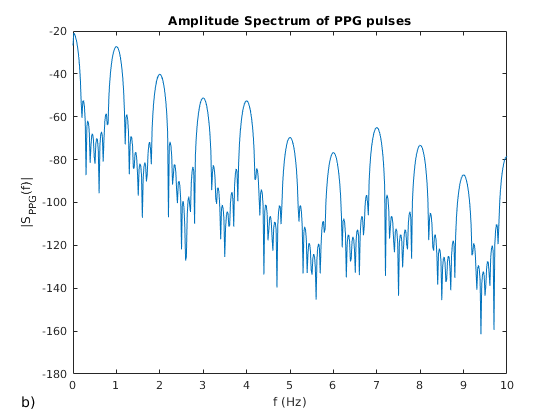


NyquistF = fs/2;
FResBPM = 0.5; %resolution (bpm) of bins in power spectrum used to determine PR and SNR
N = (60*2*NyquistF)/FResBPM; %number of bins in power spectrum

f4=figure;
n=length(a1);
 w = hanning(n);
 xw = a1.*w; 
N = 4096; %2^nextpow2(n);
    Y = fft(xw,N);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(N/2))/N;
    plot(f,mag2db(P1)) 
    title('Amplitude Spectrum of PPG pulses')
    xlabel('f (Hz)')
    ylabel('|S_{PPG}(f)|')
    xlim([0,10])
    %saveas(f4, 'Fig6.6b.jpg')
    annonation_save('b)',"Fig6.6b.jpg", SAVE_FLAG);